# Defining transfer functions in MATLAB and behaviours

Assume that the transfer function is already known and we have entered this into MATLAB in order to investigate the associated behaviour. This file gives a number of examples focussing on how to plot the step response behaviour and pole positions. Section 4 gives a quick example showing ho easily one can use multiple analysis tools at once.

You will need the control toolbox for this file and also familiarity with the content in ***transferfunctions_and_poles.mlx***. Also the file ***step_responses_with_matlab.mlx*** is useful background.

See website for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/mainindex](https://sites.google.com/sheffield.ac.uk/controleducation/mainindex)

A group of similar files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Examples of how to enter a transfer function  

- The poles and zeros can be computed using the ***pzmap.m*** file

- Steady-states, step responses and inverse Laplace

- Characterisation using multiple plots

## 1. Examples of how to enter a transfer function  

This section replicates parts of ***transferfunctions_and_poles.mlx*** for completeness.

The file tf.m takes as arguments the coefficients of the numerator and denominator to create a transfer function object. This will be clear from several examples. Some MATLAB functions interpret vectors as polynomials by allocating the coefficients to powers of 's' in order, beginning from lowest power on the right

$G\left(s\right)=\frac{1}{s^2 +5s+6};\;$has numerator with coefficient 1 and denominator with coefficients 1, 5 and 6

G=tf(1,[1 5 6])

G =
 
        1
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.



$\textrm{G2}\left(s\right)=\frac{s^2 +0\ldotp 1s+4}{{5s^3 +2s}^2 -4s+6\ldotp 3};\;$has numerator with coefficients [1, 0.1, 4] and denominator with coefficients [5, 2, -4, 6.3].

G2=tf([1 0.1 4],[5 2 -4 8.3])

G2 =
 
       s^2 + 0.1 s + 4
  -------------------------
  5 s^3 + 2 s^2 - 4 s + 8.3
 
Continuous-time transfer function.



What if some of the coefficients are zero? Simple, just include zeros in the coefficients that you supply.

$\textrm{G3}\left(s\right)=\frac{s^3 -0\ldotp 4s+5\ldotp 8}{{2\ldotp 1s^4 +7s}^2 +4\ldotp 2s};\;$note this has no $s^2$ in the numerator and no $s^3$ and $s^0$ in the denominator so we put zeros in those positions in the tf.m call line below.

G3=tf([1 0 -0.4 5.8],[2.1 0 7 4.2 0])

G3 =
 
     s^3 - 0.4 s + 5.8
  -----------------------
  2.1 s^4 + 7 s^2 + 4.2 s
 
Continuous-time transfer function.



G4 =
 
         1
  ---------------
  3 s^2 + 4 s + 5
 
Continuous-time transfer function.



## 2. The poles and zeros can be computed using the ***pzmap.m*** file  

Depending on how the statement is used you will either:

- Get numerical values into the workspace.

- A plot showing poles with 'X' and zeros with 'O'.

#### a) Compute the numerical values of poles and zeros

disp('Section 2 ')

Gpoles =    -3.0000
   -2.0000



Gzeros =

  0×1 empty double column vector



disp(' ')
disp('BELOW ARE POLE-ZERO COMPUTATIONS')

G2poles =   -1.5760 + 0.0000i
   0.5880 + 0.8412i
   0.5880 - 0.8412i


G2zeros =   -0.0500 + 1.9994i
  -0.0500 - 1.9994i


[Gpoles, Gzeros]=pzmap(G)

G3poles =    0.0000 + 0.0000i
   0.2750 + 1.8869i
   0.2750 - 1.8869i
  -0.5501 + 0.0000i


G3zeros =   -1.8709 + 0.0000i
   0.9354 + 1.4917i
   0.9354 - 1.4917i


[G2poles, G2zeros]=pzmap(G2)
[G3poles, G3zeros]=pzmap(G3)


#### b) Plot the poles and zeros on an Argand diagram

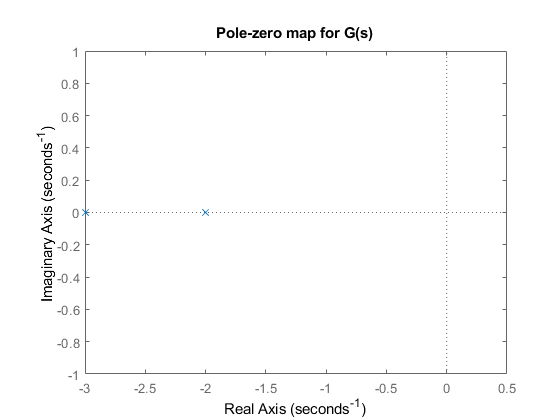

figure
pzmap(G)

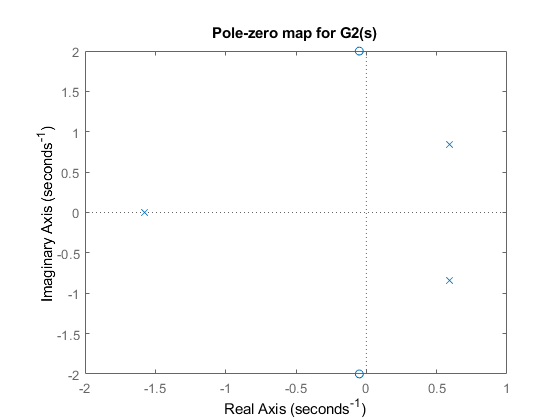

title('Pole-zero map for G(s)')
figure
pzmap(G2)

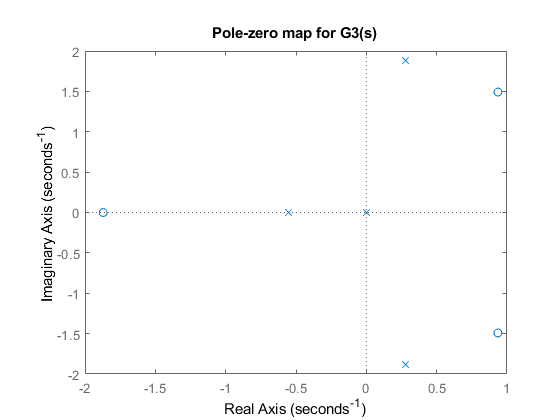

title('Pole-zero map for G2(s)')
figure
pzmap(G3)

title('Pole-zero map for G3(s)')
disp(' ')
disp('Section 3 below: Signal responses and steady-state')
disp(' ')
disp(' ')

## 3. Steady-states, step responses and inverse Laplace

If you only want a numerical value, then ***step.m*** and ***impulse.m*** are useful to create plots/values of a inverse Laplace transform which give a good dea of what to expect, albeit not a precise answer. 

- Use ***impulse.m*** to get the inverse Laplace of a signal Laplace transform.

- Use ***step.m*** to get the inverse Laplace of a system unit step response.

**Inverse Laplace of a signal**: MATLAB assumes that anything defined using*** tf.m*** is a model, but you can trick MATLAB into treating this like a signal using ***impulse.m ***which will then, in effect, do a numerical inverse Laplace.

Y=tf([1 4],[1 6 0])

Y =
 
    s + 4
  ---------
  s^2 + 6 s
 
Continuous-time transfer function.



Z = tf([1 0 -4],poly([-5 -6]))

Z =
 
      s^2 - 4
  ---------------
  s^2 + 11 s + 30
 
Continuous-time transfer function.



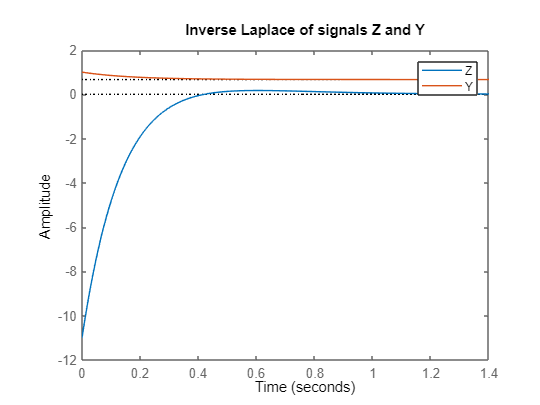

impulse(Z,Y);legend('Z','Y'); title('Inverse Laplace of signals Z and Y')

**Step responses for transfer functions**: Note that Y includes an integrator, so if this were interpreted as a transfer function model (not a signal), then the step response would diverge to infinity. Step response plots are given here.

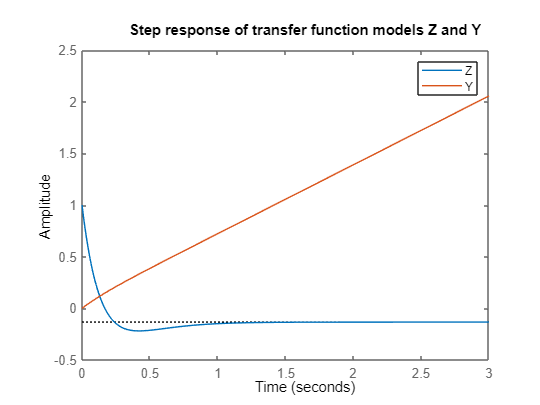

step(Z,Y,3);legend('Z','Y'); title('Step response of transfer function models Z and Y')

**Steady-state values**: The steady-state gain of a transfer function depends on the coefficients of $s^0$ which can be extracted as the last coefficients of the vectors containing the coefficients. **Warning - check for integrators to avoid infinity. **In practice, an easier tool is ***dcgain.m*** which computes the steady-state gain of a transfer function directly.

[num,den]=tfdata(Z,'v');
if den(end)~=0;steady_state_gain_Z = num(end)/den(end),end

steady_state_gain_Z = -0.1333

dcgain_Z=dcgain(Z)

dcgain_Z = -0.1333


[num,den]=tfdata(Y,'v');
if den(end)~=0;steady_state_gain_Y = num(end)/den(end),else;disp('Y has infinite gain');end

Y has infinite gain


dcgain_Y=dcgain(Y)

dcgain_Y = Inf

## 4. Characterisation using multiple plots

For characterisation we want to ask questions based on ***pzmap.m*** (section 2):

- Poles in LHP or RHP (stable or unstable).

- Ratio of real to imaginary parts of poles tells you about expected damping.

- The real parts tell you about convergence speed.

- The imaginary parts tell you the oscillation frquencies.

- Steady-state comes from the coefficients of $s^0$ (assuming no integrator and stability).

We test on a simple example here - note in general you may wish to zoom in on the parts of a plot that you find interesting.

Here the oscillatory mode is the slowest to converge so dominates the transient behaviour.


disp('Section 4 below: characterisation of system behaviour')

poles = [-0.5, -0.2+2*j,-0.2-2*j,-5];

Section 4 below: characterisation of system behaviour


G =tf(4,poly(poles))

% steady-state

G =
 
                      4
  -----------------------------------------
  s^4 + 5.9 s^3 + 8.74 s^2 + 23.22 s + 10.1
 
Continuous-time transfer function.



[num,den]=tfdata(G,'v');
steady_state_gain = dcgain(G)

pzmap(G)

steady_state_gain = 0.3960

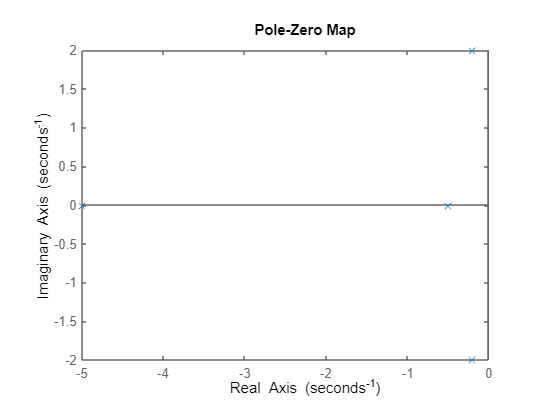

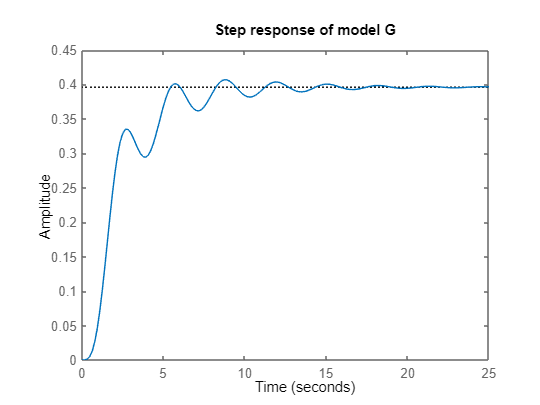

step(G); title('Step response of model G')
